(3a)

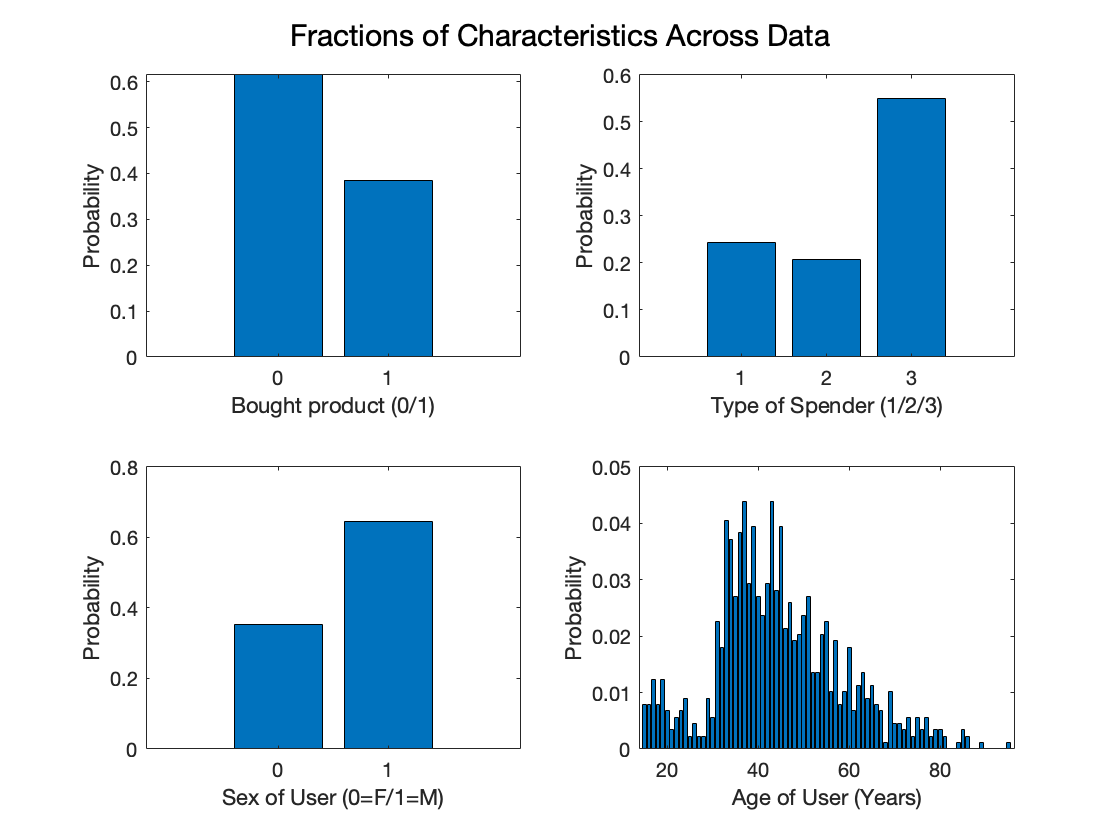

figure(1);
sgtitle("Fractions of Characteristics Across Data")
M = readmatrix("user_data.csv");
xlabs = ["Bought product (0/1)", "Type of Spender (1/2/3)", ...
            "Sex of User (0=F/1=M)", "Age of User (Years)"];
for c = 1:4
    subplot(2, 2, c);
    x = [unique(floor(M(:,c))); intmax];
    y = histcounts(M(:,c),x) / 887;
    x(end) = [];
    bar(x, y);
    xlabel(xlabs(c));
    ylabel("Probability");
end

(3b)

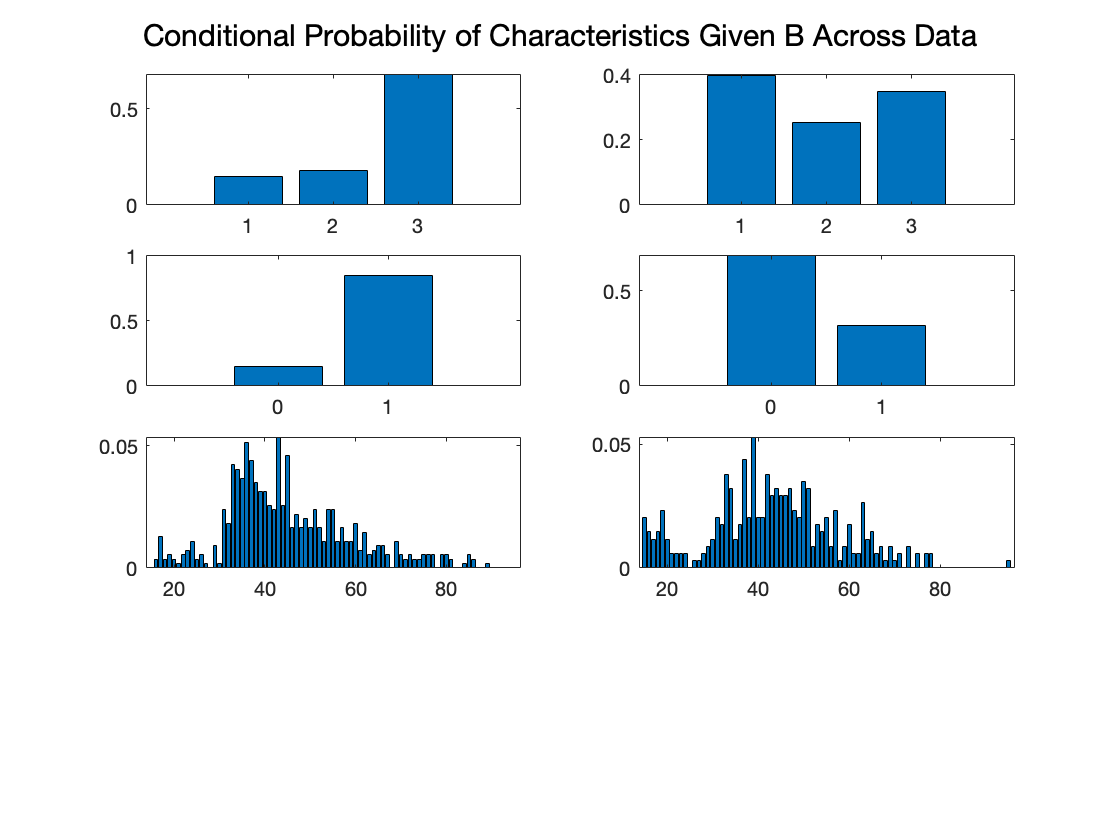

figure(2);
sgtitle("Conditional Probability of Characteristics Given B Across Data")
pb = histcounts(M(:,1),[0 1 intmax]) / 887;
for c = 2:4
    x = [unique(floor(M(:,c))); intmax];
    M1 = M(M(:,1)==0,:);
    M2 = M(M(:,1)==1,:);
    y1 = histcounts(M1(:,c),x) / (887 * pb(1));
    y2 = histcounts(M2(:,c),x) / (887 * pb(2));
    x(end) = [];
    
    subplot(4, 2, 2 * c - 3);
    bar(x, y1);
    subplot(4, 2, 2 * c - 2);
    bar(x, y2);
end

(3c) We would like to compute P(B = 0,T = 1,S = 0,A <= 55). We will proceed by using the conditional independence assumption:

P(B = 0,T = 1,S = 0,A <= 55) = P(B = 0) * P(T = 1, S = 0, A <= 55 | B = 0)

                                               = P(B = 0) * P(T = 1 | B = 0) * P(S = 0 | B = 0) * P(A <= 55 | B = 0)

Now, to get each of these terms we have to look at our code from part (b).

P(B = 0) is just `sum(M(:,1)==0)/887` . P(T = 1 | B = 0) is just `sum(M1(:,2)==1)/887` divided by P(B = 0).

pb0 = pb(1)

pb0 = 0.6144

pt1b0 = sum(M1(:,2)==1)/887/pb0

pt1b0 = 0.1468

ps0b0 = sum(M1(:,3)==0)/887/pb0

ps0b0 = 0.1486

pa55b0 = sum(M1(:,4)<=55)/887/pb0

pa55b0 = 0.7927

finalp1 = pb0 * pt1b0 * ps0b0 * pa55b0;
disp(finalp1)

    0.0106



We see that this probability is 0.0106. 

As for P(B = 1, T = 1, S = 0, A <= 55) we do the same thing except with B = 1.

pb1 = pb(2)

pb1 = 0.3856

pt1b1 = sum(M2(:,2)==1)/887/pb1

pt1b1 = 0.3977

ps0b1 = sum(M2(:,3)==0)/887/pb1

ps0b1 = 0.6813

pa55b1 = sum(M2(:,4)<=55)/887/pb1

pa55b1 = 0.8099

finalp2 = pb1 * pt1b1 * ps0b1 * pa55b1;
disp(finalp2)

    0.0846



We see that this probability is 0.0846 or 8.46%.

(3d) We use Bayes Theorem to calculate the answer to this problem:		

P(B = 0 | T = 1, S = 0, A <= 55) = P(T = 1, S = 0, A <= 55 | B = 0) * P(B = 0) / P(T = 1, S = 0, A <= 55)

P(T = 1, S = 0, A <= 55 | B = 0) * P(B = 0) = the answer to the first part in part (c).

P(T = 1, S = 0, A <= 55) is just the sum of B = 0 and B = 1 of the previous part.

Thus, by Bayes Theorem, 

pd1 = finalp1 / (finalp1 + finalp2)

pd1 = 0.1116

Similarly, P(B = 1 | T = 1, S = 0, A <= 55) is calculated in similar fashion:

pd2 = finalp2 / (finalp1 + finalp2)

pd2 = 0.8884

The two values for not buying and buying are 0.1116 and 0.8884. Thus, it is more likely that this demographic will buy the product.